# A von Karman plate with 1:1 internal resonance

In this example, we consider a simply-supported von Karman square plate subject to harmonic excitation. Due to the geometric symmetry, the natural frequenices of the second and the third modes are the same. In other words, the system has 1:1 internal resonance between the two modes. We extract the forced response curve using SSM reduction. The particularity of this example is that the SSM is not a slow one, but an intermediate SSM and has dimension four.

 See [1] for the details of this model, and [2] for the description of this example.

[1] Li, M., Jain, S., & Haller, G. (2021). Nonlinear analysis of forced mechanical systems with internal resonance using spectral submanifolds-Part I: Periodic response and forced response curve. *Nonlinear Dynamics* 110, 1005-1043. [DOI: 10.1007/s11071-022-07714-x](https://doi.org/10.1007/s11071-022-07714-x)

[2] Cenedese, M., Marconi, J., Haller, G., & Jain, S. (2023). Data-assisted non-intrusive model reduction for forced nonlinear finite elements models. Preprint: [arXiv: 2311.17865](https://arxiv.org/abs/2311.17865) 

The finite element code taken from the following package:

Jain, S., Marconi, J., Tiso P. (2020). YetAnotherFEcode (Version v1.1). Zenodo. [http://doi.org/10.5281/zenodo.4011282](http://doi.org/10.5281/zenodo.4011282) 

See the `README` of the main repository to retrieve simulations data.

clearvars
close all
format shortg
clc

% Setup colors
colors = colororder; colSSMT = 5; colSSML = 7; colFOM = 1;

## Example setup

The $N$-degree of freedom dynamical system is of the form


$$\mathbf{M\ddot{q}} + \mathbf{C\dot{q}} + \mathbf{Kq} + \mathbf{f}(\mathbf{q},\mathbf{\dot{q}}) 
= \mathbf{0}$$


where $\mathbf{f}=\mathcal{O}(|\mathbf{q}|^2,|\mathbf{\dot{q}}|^2,|\mathbf{q}||\mathbf{\dot{q}}|)$ represents the nonlinearities and $\mathbf{M}$, $\mathbf{C}$, and $\mathbf{K}$ are the $n\times n$ mass, stiffness, and damping matrices, respectively.

We rewrite the system in first-order form as


$$\mathbf{\dot{x}} = \mathbf{A}\mathbf{x} + \mathbf{G}(\mathbf{x}) = \mathbf{F}(\mathbf{x})$$


with

$\mathbf{x}=\left[\begin{array}{c}\mathbf{q}\\\dot{\mathbf{q}}\end{array}\right],\quad\mathbf{A}=\left[\begin{array}{cc}\mathbf{0}   & \mathbf{I}\\-\mathbf{M}^{-1}\mathbf{K} & -\mathbf{M}^{-1}\mathbf{C} \end{array}\right],\quad\mathbf{G}(\mathbf{x})=\left[\begin{array}{c}   \mathbf{0} \\ -\mathbf{M}^{-1}\mathbf{f}(\mathbf{x})\end{array}\right]$.

l = 1; % length of domain [m]
b = 1;  % breadth of domain [m]
t = 1e-2; % thickness of plate [m]
w = 0.0; % curvature parameter (height of the midpoint relative to ends) [m]
% material properties
E     = 70e9;  % 70e9 % 200e9 % Young's modulus [Pa]
rho   = 2700; % 2700 % 7850 % density [kg/m^3]
nu    = 0.33;    % Poisson's ratio 
kappa = 1e5; % material damping modulus 1e8

% Mesh
nElements = 10;
nl = nElements;
nb = nElements;
bc = 'SSSS';


## Generate model

Building FE model


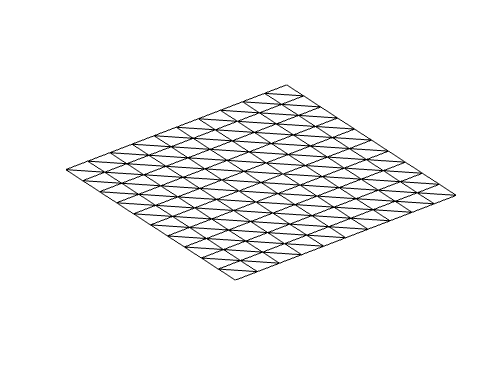

Assembling M,C,K matrices
Applying boundary conditions
Solving undamped eigenvalue problem
The circular natural frequencies of the first five modes:


omega =        306.69
       763.59
       767.75
       1218.8
       1531.1


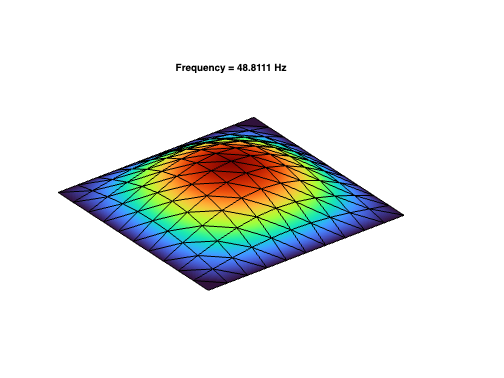

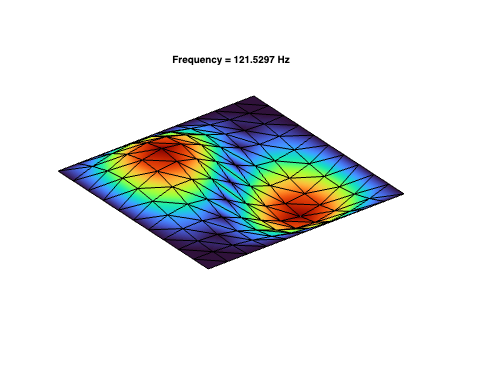

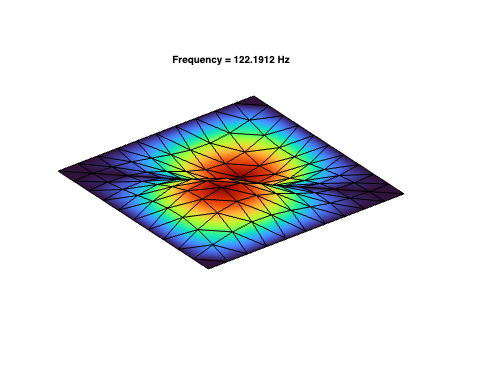

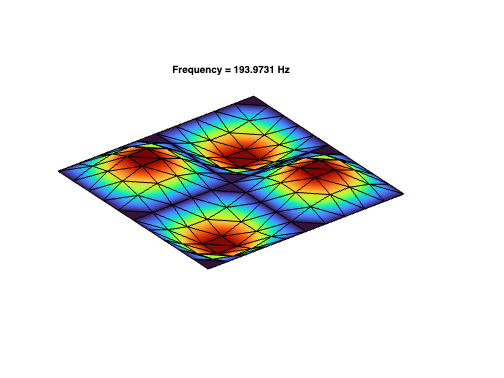

Using Rayleigh damping
Getting nonlinearity coefficients
Loaded tensors from storage
Assembling external force vector


[M,C,K,fnl,~,outdof, Model] = buildModel(l,b,t,w,E,rho,nu,kappa,bc,nl,nb);

n = length(M); % number of degrees of freedom
disp(['Number of degrees of freedom = ' num2str(n)])

Number of degrees of freedom = 606


disp(['Phase space dimensionality = ' num2str(2*n)])

Phase space dimensionality = 1212


f_0 = zeros(n,1);
f_0(outdof(1)) = 100;
epsilon = 0.5;


Preliminaries: import the linear part without recomputing it.

if ~isfile('linpart.mat')
    m = 10;
    [W,A,V,lambda] = linearpart(M,C,K,m);
    save('linpart.mat',"W","A","V","lambda")
else
    load('linpart.mat')
end

## Define master modes and linear part of the dynamics 

We initialize the base properties of the SSM, i.e., its linear part, which we know from the linear dynamics of the model. In this case, we target an intermediate four-dimensional SSM of the system, which features an internal $1:1$ resonance.

masterModes = [3 5 4 6]; % Modal displacements and modal velocities
SSMDim = length(masterModes);
Ve = V(:,masterModes); % Mode shape
We = W(masterModes,:); % Projection to mode shape
Ae = full(We*A*Ve) % Reduced, linearized dynamics

Ae =             0            0            1   2.0339e-13
            0            0   2.0345e-13            1
  -5.8308e+05  -1.2276e-07      -3.3323  -6.8996e-13
  -1.2034e-07  -5.8944e+05  -6.8166e-13      -3.3578


Load and displacement vector

displacementVector = zeros(1,n); displacementVector(outdof) = 1;
loadVector = f_0;  %  could also be set as modal ones

## Compare linear and nonlinear response via modal displacement

We characterize the linear and nonlinear regimes via a static modal analysis, which serves to pick appropriate initial conditions for the trajectories we need to learn the SSM from data.

Displacement along the first mode

Solving undamped eigenvalue problem
Mode shape
  -0.00014705
  -0.00014181
   2.7274e-18
    -0.069108
  -0.00078624
   8.0752e-18
     -0.12208
  -0.00081778
   8.9702e-18
     -0.14761
   -0.0005186
  -2.5233e-17
     -0.14319
   0.00013401
  -6.0444e-19
     -0.11506
   0.00088987
  -3.3621e-18
    -0.075457
    0.0015077
   -5.682e-18
    -0.037929
    0.0016542
  -1.9181e-18
    -0.012192
     0.001569
  -2.0465e-17
   -0.0011337
   0.00037124
   1.3782e-17
    0.0002299
    0.0002299
  -3.0398e-19
  -0.00078592
    -0.069069
   5.1454e-18
   2.2008e-19
  -1.3482e-18
    0.0065286
    -0.061123
    -0.061154
  -1.8717e-17
  -1.2506e-18
  -9.1481e-19
     0.011494
     -0.10659
    -0.038893
   6.3512e-18
  -1.8541e-18
  -1.2021e-18
     0.013834
     -0.12686
   -0.0095195
    8.948e-18
  -3.4444e-18
   3.6607e-18
     0.013321
     -0.12005
     0.018009
   4.1543e-19
  -2.4455e-18
   1.8959e-18
     0.010575
    -0.092426
     0.035879
   1.0221e-18
  -8.9804e-19
  -3.9333e-20
 

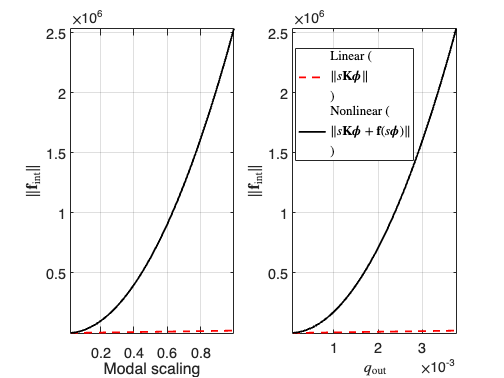

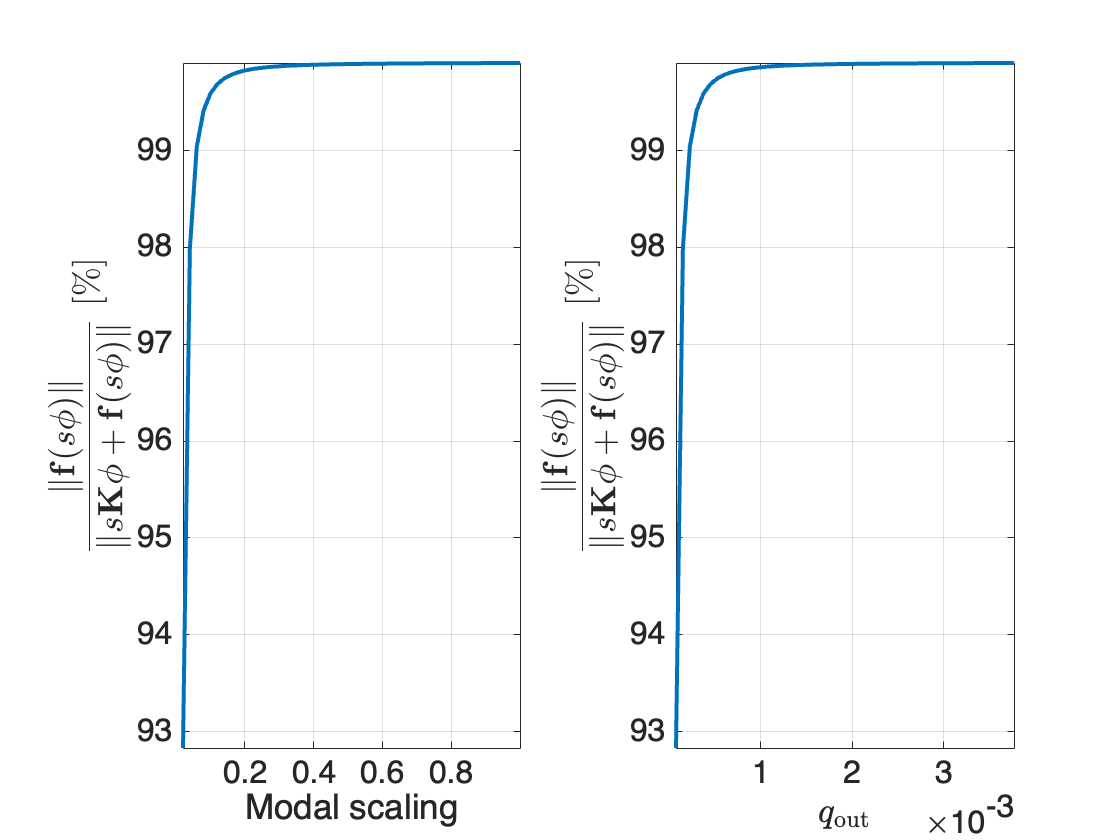

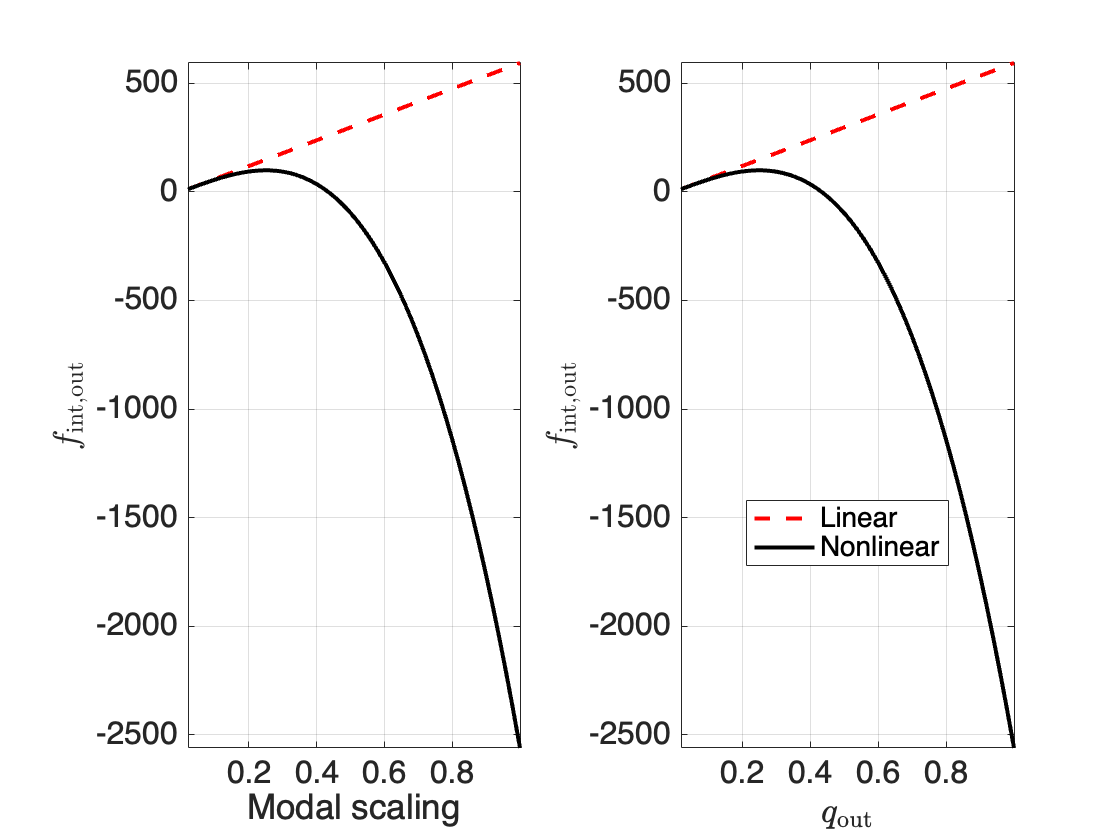

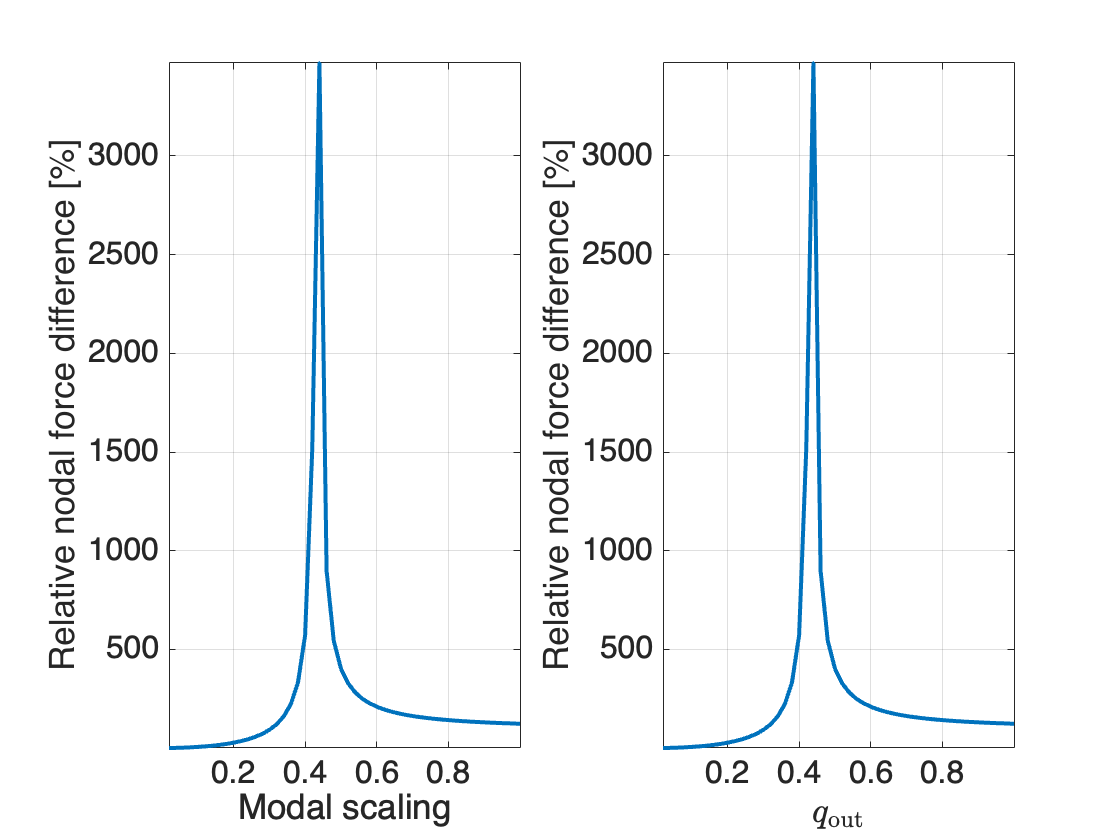

Displacement at output DOF: 0.0037652


iMode = 2; scalingfactor1 = 1e0; nsteps = 50; outdof1 = outdof(1);
[phi1, relativeDiffForceNorm] = modal_analysis(Model,scalingfactor1,nsteps,outdof1,true,iMode);

Pick up two initial trajectories that has high expected nonlinear content

indIC1 = [nsteps, nsteps-1];
IC1 = [phi1*(scalingfactor1*indIC1/nsteps);zeros(n,length(indIC1))];

Displacement along the second mode

Solving undamped eigenvalue problem
Mode shape
   0.00086981
  -0.00086881
   1.1961e-19
    0.0021813
  -0.00082061
   2.6942e-19
     0.013476
   -0.0015382
   2.5018e-19
     0.038394
   -0.0014675
  -7.6041e-19
     0.075069
   -0.0010419
  -4.3955e-20
      0.11411
  -0.00035574
  -1.6904e-19
      0.14218
   0.00027782
  -1.6181e-19
       0.1469
   0.00065313
   -7.516e-20
      0.12173
   0.00055752
  -5.3815e-19
     0.069069
   0.00029876
   4.0785e-19
   0.00021654
  -0.00021654
  -1.1683e-20
   0.00082087
   -0.0021986
   1.5146e-19
   5.1067e-21
  -4.2387e-20
   1.0145e-06
    -0.003085
    0.0030639
   -5.012e-19
  -3.9857e-20
  -2.7017e-20
  -0.00094763
    0.0030592
      0.01504
   1.5878e-19
  -6.3305e-20
  -3.8177e-20
   -0.0032802
     0.023484
     0.029219
   2.3562e-19
  -1.0228e-19
   1.1033e-19
   -0.0067896
     0.056362
     0.037822
   3.6029e-21
  -8.3362e-20
   6.1709e-20
    -0.010567
     0.092836
     0.034856
   1.3954e-20
  -3.4326e-20
   1.8148e-21
 

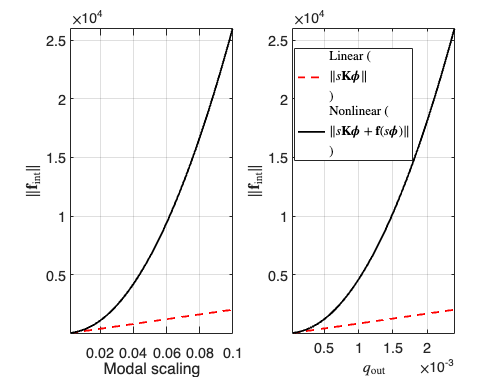

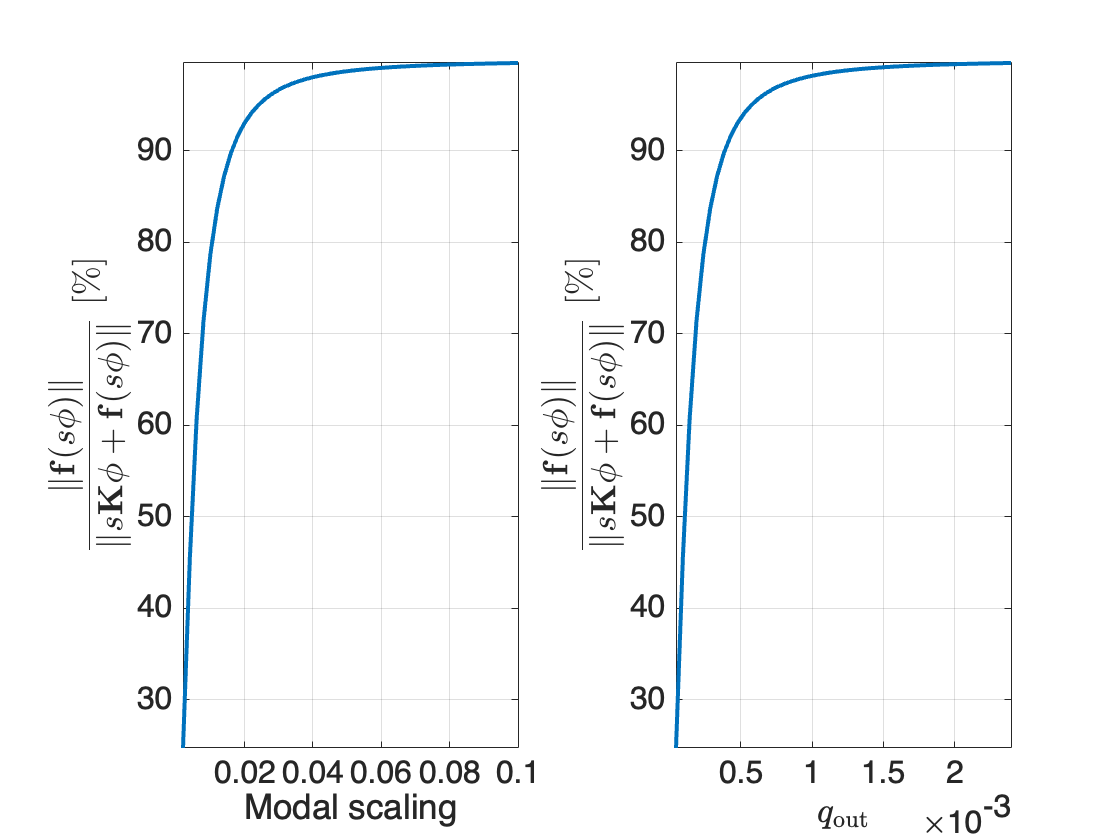

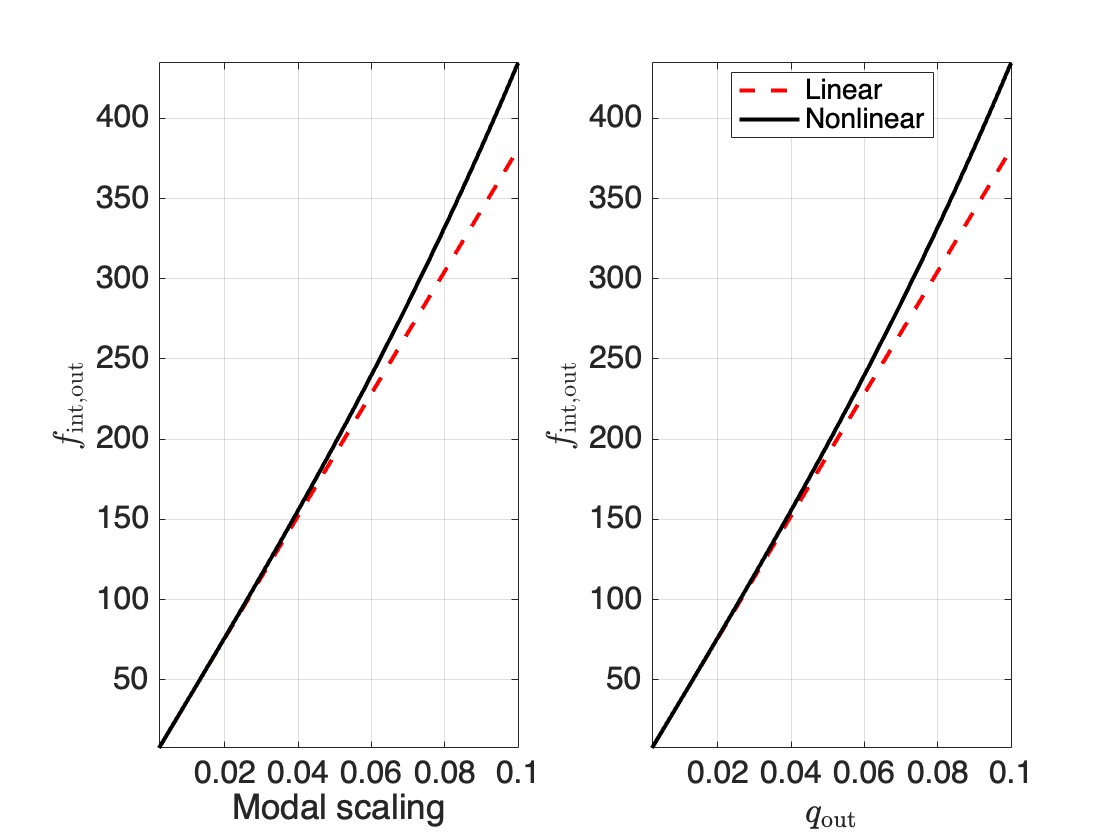

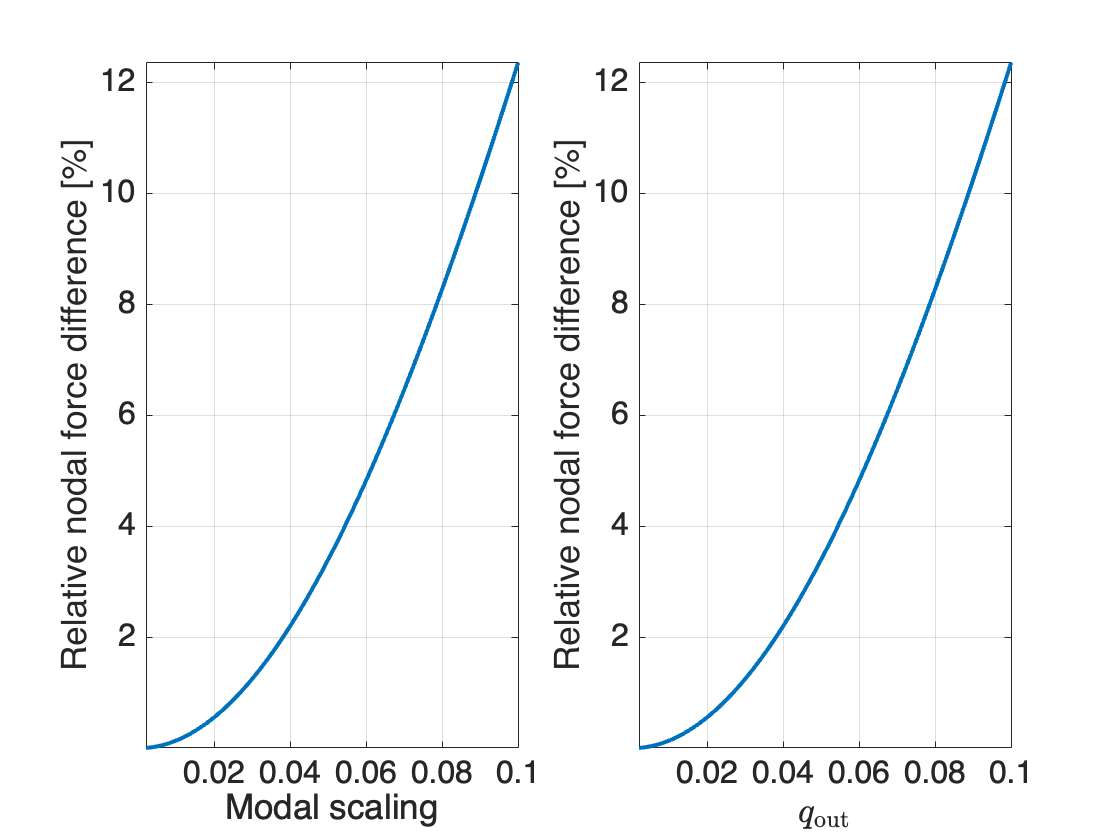

Displacement at output DOF: 0.0023927


iMode = 3; scalingfactor2 = 1e-1; nsteps = 50; outdof2 = outdof(1);
[phi2, relativeDiffForceNorm2] = modal_analysis(Model,scalingfactor2,nsteps,outdof2,true,iMode);

Pick up two initial trajectories that has high expected nonlinear content

indIC2 = [nsteps, nsteps-1];
IC2 = [phi2*(scalingfactor2*indIC2/nsteps);zeros(n,length(indIC2))];

Pick combination of initial conditions along the both the modes for training and testing

a = rand; b = rand; 
ICs = [IC1, IC2, a*IC1 + b*IC2];
indTrain = [1 3 5];
indTest = [2 4 6];

Define the linear regime at 1 % relative force

linearDisplacementReference = scalingfactor1*(sum(relativeDiffForceNorm<1)+1)/nsteps;
nonlinearDisplacementReference = scalingfactor1*max(indIC1)/nsteps;
desiredAmplitudeDecay = nonlinearDisplacementReference/linearDisplacementReference;

## **Generate decaying trajectories via time integration**

We define observables and timescales. The computation of integration time is estimated from the linear decay that gets from the defined nonlinear amplitude to linear regime. We set the sampling time to capture approximately a fixed number points per period on the faster time scale. Then, we integrate using the initial conditions we obtained from the static analysis. Here, we use a pre-computed data set to avoid excessive computations.

observable = @(x) x; % Observe the full phase space
slowTimeScale = 2*pi/abs(lambda(2));
fastTimeScale = 2*pi/abs(lambda(3));
% The computation of integration time is estimated from the linear decay that 
% gets from the nonlinear amplitude to linear regime.
newSimulation = false;
if newSimulation
    numberPeriodsSlow = floor(log(desiredAmplitudeDecay)/...
        (2*pi*(-real(lambda(1))/abs(lambda(1)))))
    endTime = numberPeriodsSlow*slowTimeScale;
    % Set the sampling time to capture approximately 50 points per period on the 
    % faster time scale
    numberPeriodsFast = floor(endTime/fastTimeScale);
    numberPointsPerPeriod = 50;
    nSamp = numberPeriodsFast*numberPointsPerPeriod+1;
    dt = endTime/(nSamp-1);
    xData = integrateTrajectoriesGalphaDirect(Model, endTime, ICs, nSamp, observable);
    loadShape = f_0;
    DataInfo = struct('nElements', Model.Mesh.nElements, 'loadShape', loadShape);
    save('dataVKDecay2DGalphaModal.mat', 'DataInfo', 'xData', 'dt', 'endTime', 'nSamp')
else
    load("../../data/vonkarmanplateIR/dataVKDecay2DGalphaModalData2.mat")
end

## Visualize data

% This step is here not mandatory as we know that the SSM exists in the
% phase space (no embedding needed)
xData = coordinatesEmbedding(xData, SSMDim, 'ForceEmbedding', 1);

The embedding coordinates consist of the measured states.


Data filtering: We need to make sure that the data that we use to identify the manifold lies close to it. We can do this by plotting a spectrogram of the observables of interest. In general, there may be many vibratory modes present at first, but the faster ones quickly die out.

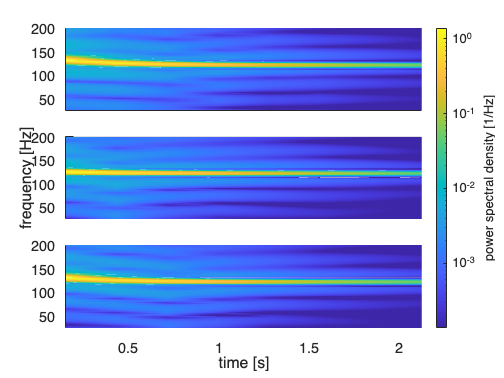

fig = customFigure();
fontName = 'helvetica';
fontSize = 16;
tiledlayout(3,1);
nexttile
showSpectrogram(xData(1,:), outdof(1), 1);
ylim([25,200])
set(gca, 'fontname', fontName)
set(gca, 'fontsize', fontSize)
xticks([])
nexttile
showSpectrogram(xData(3,:), outdof(1), 1);
ylim([25,200])
set(gca, 'fontname', fontName)
set(gca, 'fontsize', fontSize)
ylabel('frequency [Hz]')
xticks([])
nexttile
showSpectrogram(xData(5,:), outdof(1), 1);
ylim([25,200])
xlabel('time [s]')
cb = colorbar;
cb.Layout.Tile = 'east';
cb.Label.String = 'power spectral density [1/Hz]';
set(gca, 'fontname', fontName)
set(gca, 'fontsize', fontSize)

We plot the observables of interest over time for closer inspection. 

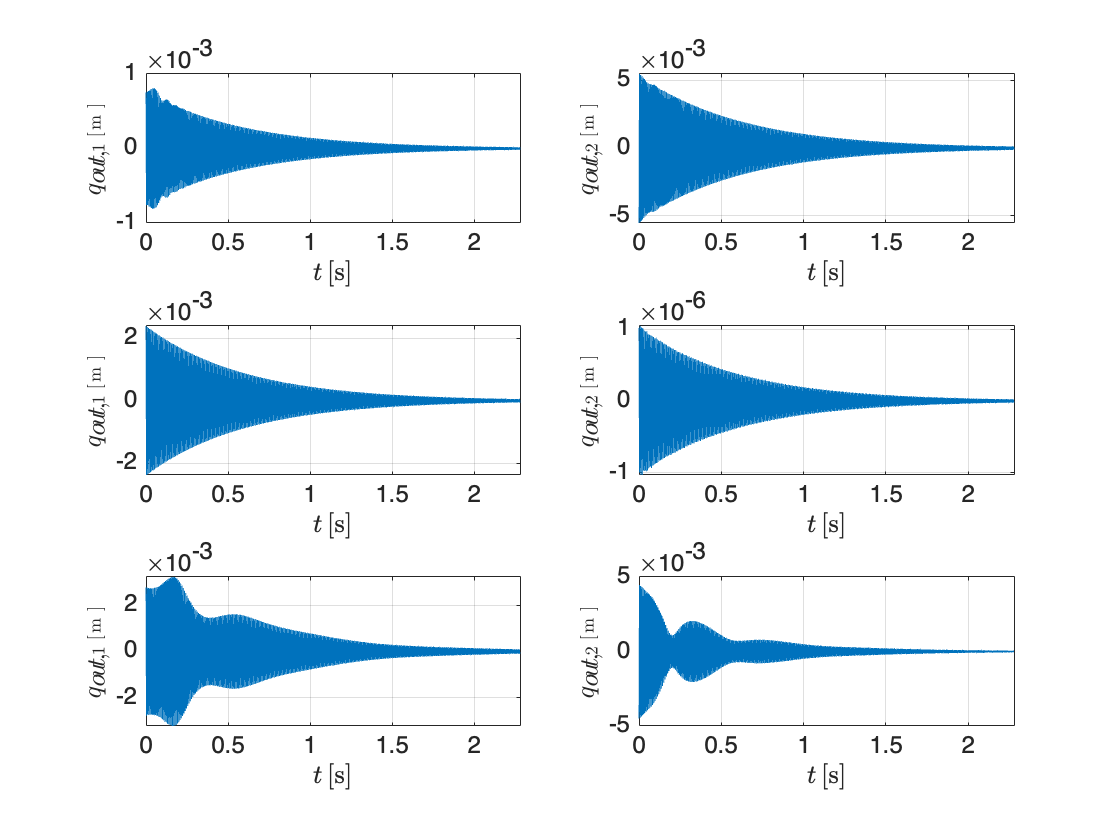

fig = customFigure('subPlot',[3 2]);
for iTraj = [1 3 5]
    subplot(3,2,iTraj)
    plot(xData{iTraj,1}, xData{iTraj,2}(outdof(1),:));
    xlabel('$t \, [$s$]$','Interpreter','latex'); 
    ylabel('$q_{out,1} \, [$m$]$','Interpreter','latex'); 
    subplot(3,2,iTraj+1)
    plot(xData{iTraj,1}, xData{iTraj,2}(outdof(2),:));
    xlabel('$t \, [$s$]$','Interpreter','latex'); 
    ylabel('$q_{out,2} \, [$m$]$','Interpreter','latex'); 
end

## Truncate transient data from trajectories

We must however remove the first transient to fulfill the assumption that trajectories lie close to the SSM. We keep only the time interval |sliceInt|.

sliceInt = [2*slowTimeScale, endTime];
xDataTrunc = sliceTrajectories(xData, sliceInt);

## Datadriven manifold fitting

The measured trajectories are initialized to lie close to the manifold of interest that is tangent at the origin to the eigenspace spanned by the columns of $\mathbf{V}_e$. 

As we also know the projection $\mathbf{W}_e$ to this eigenspace, we define the modal coordinates as $\mathbf{y} = \mathbf{W}_e \mathbf{x}$. These are the reduced coordinates for our graph style parametrization of the manifold, gauranteed to exists near the origin. We then use the data to learn the nonlinear feature of the manifold geometry, represented via polynomials. Indeed, we seek the $2N\times m_M$ polynomial coefficient matrix $H$ of the manifold on the form

$\mathbf{x} = \mathbf{V}_e \mathbf{y}  + \mathbf{H}  \mathbf{\phi}_{m,2:M}(\mathbf{y} )$,

where the function $\mathbf{\phi}_{m,2:M}(\mathbf{y})$ computes a vector of all $m_M$ monomials from orders 2 up to $M$ of an $m$-vector $\mathbf{y}$. From SSM theory, the tangent space of the manifold is $\mathbf{V}_e$. The coefficients $\mathbf{H}$are obtained via least squares regression.

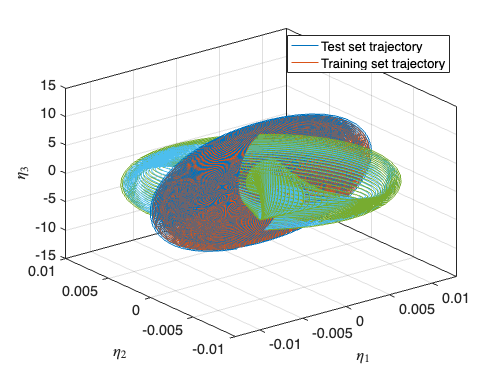

SSMOrder = 3;

% Get projection or modal coordinates 
SSMDim = size(Ve,2);
yDataTrunc = xDataTrunc;
nTraj = size(xDataTrunc,1);
for iTraj = 1:nTraj
    yDataTrunc{iTraj,2} = We*xDataTrunc{iTraj,2};    
end

% Plot reduced coordinates
plotReducedCoordinates(yDataTrunc);
legend({'Test set trajectory', 'Training set trajectory'})
if SSMDim>2
   view(3) 
end


% Compute nonlinear part of the parametrization
IMInfo = IMGeometry(xDataTrunc(indTrain,:), SSMDim,SSMOrder,...
         'reducedCoordinates',yDataTrunc(indTrain,:),'Ve',Ve,'outdof',outdof); 
IMInfo.chart.map = @(x) We*x;                          

% Parametrization error on test trajectory
normedTrajDist = computeTrajectoryErrors(liftTrajectories(IMInfo,...
    yDataTrunc), xDataTrunc);
staticNMTE = mean(normedTrajDist(indTest))*100; % in percentage

disp(['Reconstruction error = ' num2str(staticNMTE) '%'])

Reconstruction error = 0.29665%


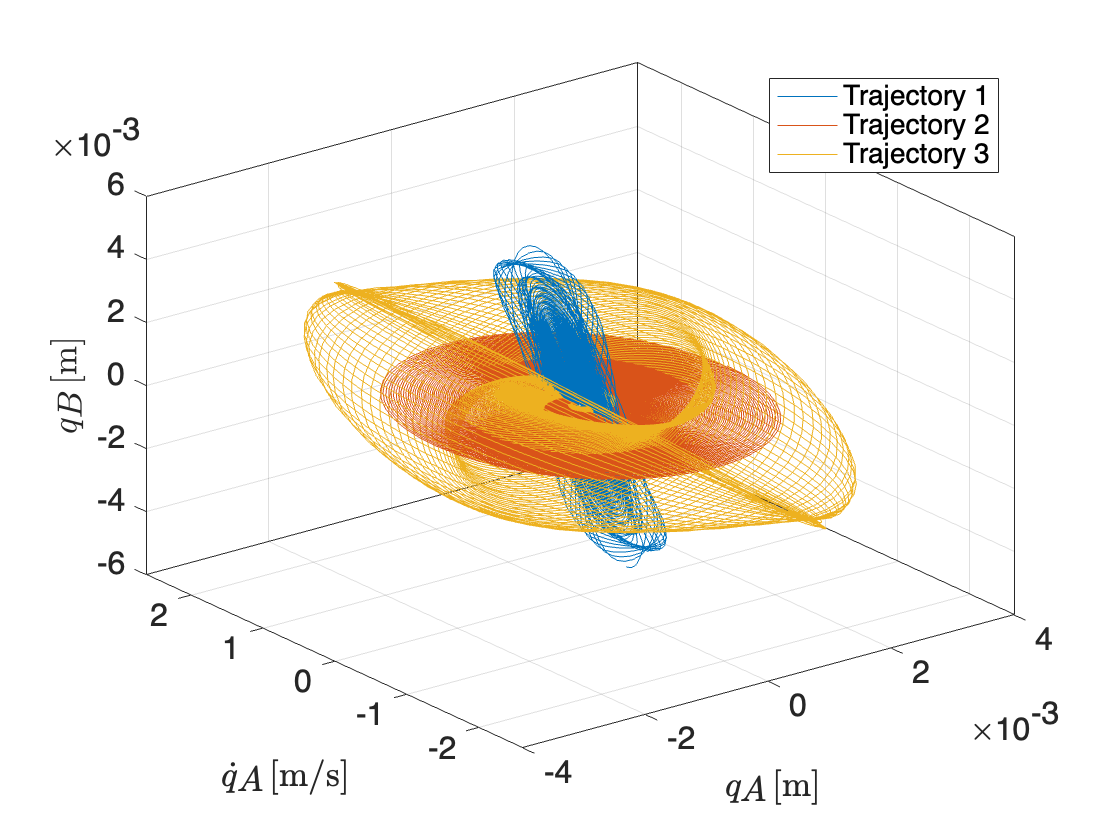


% Plot physical coordinates
customFigure;
for iTraj = indTrain
    plot3(xData{iTraj,2}(outdof(1),:),xData{iTraj,2}(outdof(1)+size(M,1),:),xData{iTraj,2}(outdof(2),:))
end
xlabel('$q_{A}$ [m]','interpreter','latex')
ylabel('$\dot{q}_{A}$ [m/s]','interpreter','latex')
zlabel('$q_{B}$ [m]','interpreter','latex')
legend('Trajectory 1','Trajectory 2','Trajectory 3')
view(3)

## Reduced dynamics on the manifold

We compute a model for the reduced dynamics with the truncated training data projected onto the manifold. The function `IMDynamicsMech` finds the dynamics (considering that we know the linear part)

$\dot{\mathbf{y}}= \mathbf{A}_e \mathbf{y}  + \mathbf{H}_r  \mathbf{\phi}_{m,2:M}(\mathbf{y} )$,

where $\mathbf{\phi}(\mathbf{y})$ again computes a vector of all monomials of $\mathbf{u}$, and $\mathbf{H}_r$ is a matrix of polynomial coefficients of the form


$$\mathbf{H}_r = \left[\matrix{  \mathbf{0} \cr  \mathbf{W}_r } \right]$$


Then, we find from data the extended normal form, which expedites system characterization and computation of periodic forced responses.

ROMOrder = 5;
freqNorm = [1 1];

RDInfo = IMDynamicsMech(yDataTrunc(indTrain,:), ...
    'R_PolyOrd', 1,'N_PolyOrd', ROMOrder, 'style', 'normalform', ...
    'R_coeff',Ae,'rescale',1,'frequencies_norm',freqNorm,'MaxIter',5e3);

Estimation of the reduced dynamics...  Done. 
Estimation of the reduced dynamics in normal form...
                                                        First-order 
 Iteration  Func-count       f(x)        Step-size       optimality
     0           1          64.5768                           155
     1           3          40.5944     0.00122686            127  
     2           5          35.6058       0.482621            136  
     3           7          32.3071       0.349418           17.9  
     4           8          31.6722              1           16.6  
     5           9          29.4008              1           43.8  
     6          11          29.1837       0.219698           17.3  
     7          12          28.8577              1           11.8  
     8          13          28.5823              1           2.27  
     9          14          28.5556              1           2.26  
    10          15          28.4543              1           3.51  
    11          16


% We transform the truncated initial condition of our test trajectory according to 
% the obtained change of coordinates, and integrate our reduced order evolution rule 
% to predict the development of the trajectory. 
[yRec, etaRec, zRec] = advect(IMInfo, RDInfo, xDataTrunc);

% Evaluation of reduced dynamics
% The error NMTE is computed as the average distance of the predicted trajectory 
% to the measured one in the full state space.
normedTrajDist = computeTrajectoryErrors(yRec, xDataTrunc);
NMTE = mean(normedTrajDist(indTest))*100;
disp(['Normalized mean trajectory error = ' num2str(NMTE) '%'])

Normalized mean trajectory error = 5.7168%


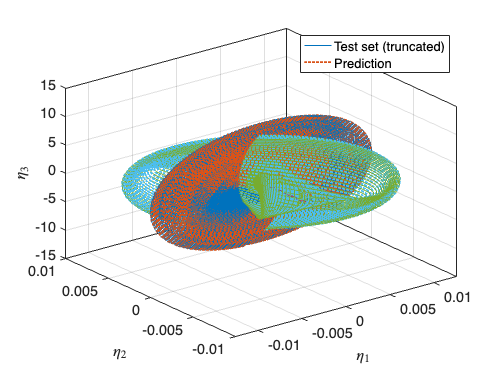


% We plot the true test set trajectory in the reduced coordinates and compare it to 
% the prediction. 
plotReducedCoordinates(yDataTrunc(indTest,:), etaRec(indTest,:))
legend({'Test set (truncated)', 'Prediction'})
if size(Ae,1)==2
    % Plot SSM with trajectories in the normal form reduced coordinates
    plotSSMandTrajectories(IMInfo, outdof, xDataTrunc(indTest,:), ...
        zRec(indTest,:), 'NFT', RDInfo.transformation.map)
    view(-100,20); legend('off')
else
    view(3)
end

We plot the model predictions in physical coordinates. The reduced model seems to do well on previously unseen data, provided that it is close to the manifold.

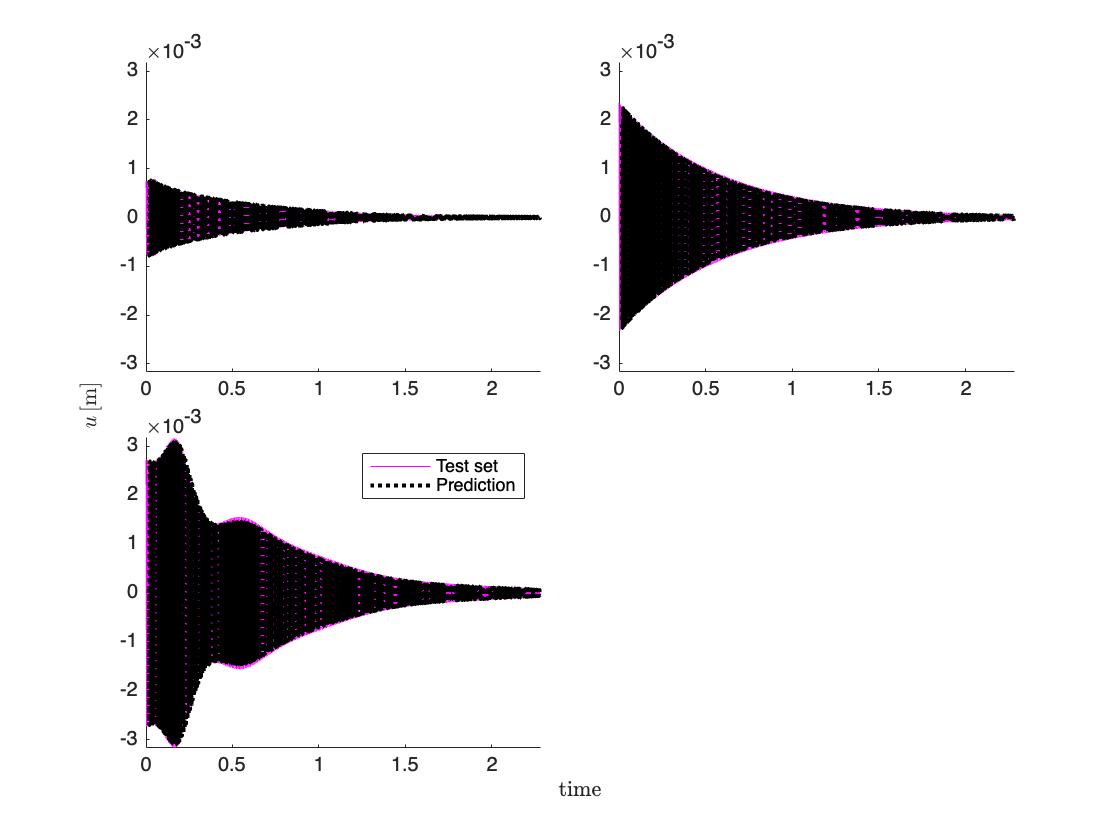

plotTrajectories(xData(indTest,:), yRec(indTest,:), 'm','PlotCoordinate',...
    outdof(1), 'DisplayName', {'Test set', 'Prediction'})
ylabel('$u \, [$m$]$','Interpreter','latex')

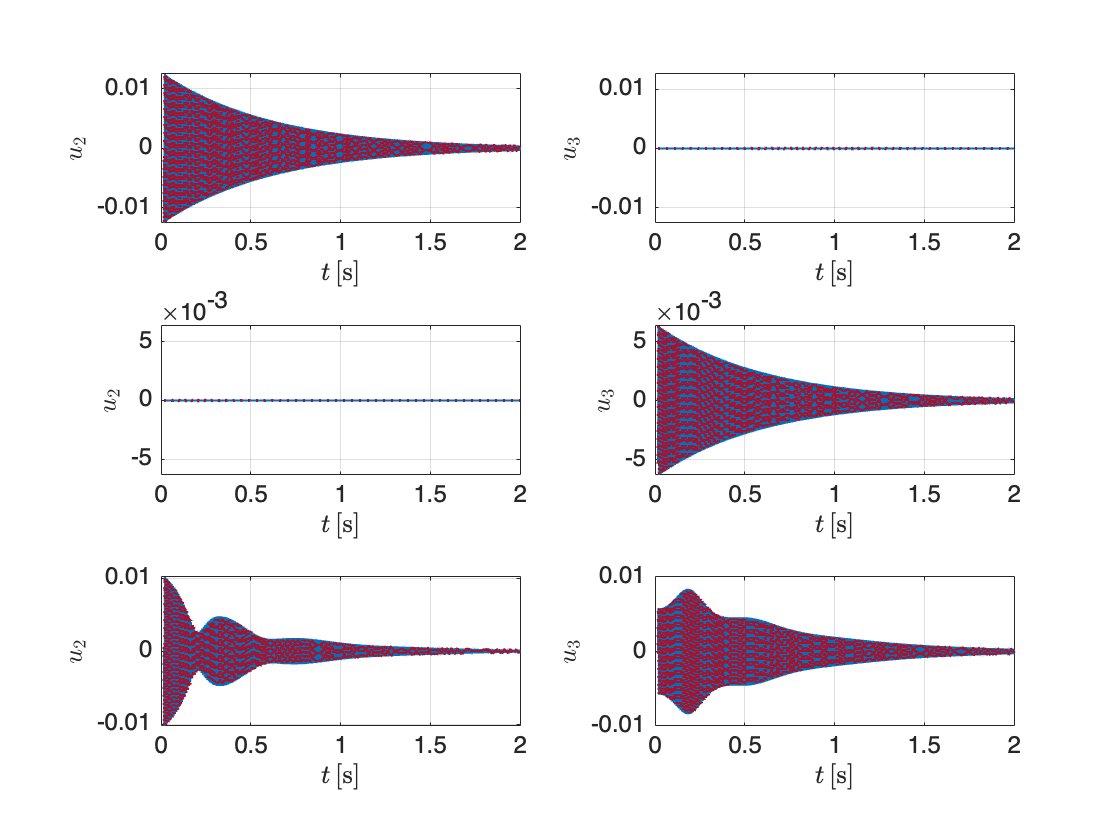


fig = customFigure('subPlot',[3 2]);
for iTraj = indTest
    subplot(3,2,iTraj-1)
    plot(yDataTrunc{iTraj,1},yDataTrunc{iTraj,2}(1,:),'k','Linewidth',1,'Color',colors(colFOM,:))
    plot(etaRec{iTraj,1},etaRec{iTraj,2}(1,:),':','Linewidth',1.5,'Color',colors(colSSML,:))
    xlabel('$t \, [$s$]$','Interpreter','latex'); 
    ylabel('$u_2$','Interpreter','latex'); xlim([0 2])
    if iTraj == indTest(2); ylim([-1 1]*max(abs(yDataTrunc{iTraj,2}(2,:)))); end
    subplot(3,2,iTraj)
    plot(yDataTrunc{iTraj,1},yDataTrunc{iTraj,2}(2,:),'k','Linewidth',1,'Color',colors(colFOM,:))
    plot(etaRec{iTraj,1},etaRec{iTraj,2}(2,:),':','Linewidth',1.5,'Color',colors(colSSML,:))
    xlabel('$t \, [$s$]$','Interpreter','latex'); 
    ylabel('$u_3$','Interpreter','latex'); xlim([0 2])
    if iTraj == indTest(1); ylim([-1 1]*max(abs(yDataTrunc{iTraj,2}(1,:)))); end
end

## Adding forcing to the ROM

Outer directions: either consider all outer modes or a subset

nModes = size(V,2);
outerModes = setdiff(1:nModes,masterModes);
Vo = V(:,outerModes); 
Wo = W(outerModes,:); Lo = full(Wo*A*Vo);

Forcing vector

forcingVectors = [zeros(n,1); M\loadVector];

Construct time periodic SSM model

[IMInfoF,RDInfoF] = forcedSSMROM(IMInfo,RDInfo,'nForcingFrequencies',1,...
         'forcingVectors',forcingVectors,'We',We,'Lo',Lo,'Vo',Vo, 'Wo',Wo);

## Generate Frequency Responses

We compute them also with SSMTool in order to compare the results (see the papers above for additional validations and comparisons).


 Run='SSMLearnvonKarmanPlateIR.ep': Continue equilibria along primary branch.

    STEP   DAMPING               NORMS              COMPUTATION TIMES
  IT SIT     GAMMA     ||d||     ||f||     ||U||   F(x)  DF(x)  SOLVE
   0                          7.92e-03  1.08e+03    0.0    0.0    0.0
   1   1  1.00e+00  5.62e-03  3.62e-05  1.08e+03    0.0    0.0    0.0
   2   1  1.00e+00  2.90e-05  2.14e-10  1.08e+03    0.0    0.0    0.0
   3   1  1.00e+00  2.36e-10  1.20e-15  1.08e+03    0.0    0.0    0.0

 STEP      TIME        ||U||  LABEL  TYPE            om         rho1         rho2          th1          th2          eps
    0  00:00:00   1.0799e+03      1  EP      7.6359e+02   1.4414e-02   3.3645e-02   1.8524e-01   4.3780e+00   2.0000e-01
   10  00:00:00   1.0760e+03      2          7.6081e+02   7.6587e-03   2.2740e-02   1.0582e+00   4.4859e+00   2.0000e-01
   20  00:00:00   1.0710e+03      3          7.5729e+02   4.0024e-03   1.5684e-02   1.3180e+00   4.5572e+00   2.0000e-01
   30  00:00:00

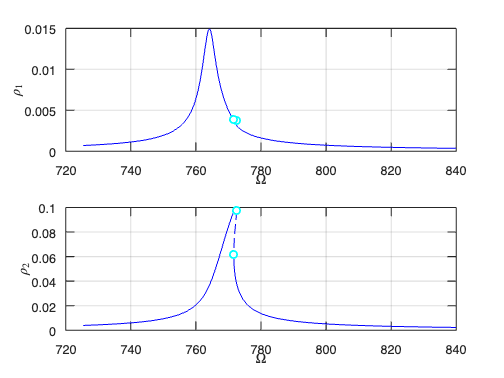

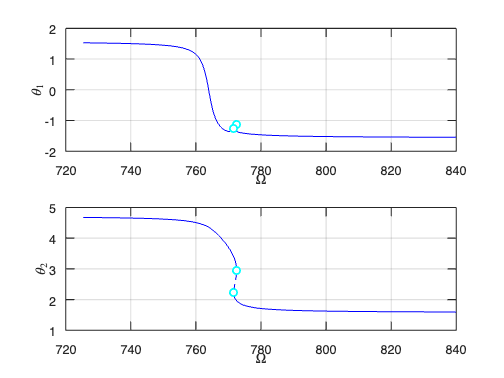


 Run='SSMLearnvonKarmanPlateIR.ep.ep': Continue equilibria along primary branch.

    STEP   DAMPING               NORMS              COMPUTATION TIMES
  IT SIT     GAMMA     ||d||     ||f||     ||U||   F(x)  DF(x)  SOLVE
   0                          5.17e-02  1.08e+03    0.0    0.0    0.0
   1   1  1.00e+00  4.81e-03  1.44e-04  1.08e+03    0.0    0.0    0.0
   2   1  1.00e+00  5.84e-05  1.18e-09  1.08e+03    0.0    0.0    0.0
   3   1  1.00e+00  7.08e-10  1.69e-15  1.08e+03    0.0    0.0    0.0

 STEP      TIME        ||U||  LABEL  TYPE            om         rho1         rho2          th1          th2          eps
    0  00:00:00   1.0799e+03      1  EP      7.6359e+02   2.2158e-02   5.6418e-02   4.7644e-01   4.4423e+00   4.0000e-01
   10  00:00:00   1.0759e+03      2          7.6074e+02   1.3092e-02   4.1754e-02   1.1176e+00   4.5057e+00   4.0000e-01
   20  00:00:00   1.0709e+03      3          7.5721e+02   7.5834e-03   3.0256e-02   1.3294e+00   4.5629e+00   4.0000e-01
   30  00:00

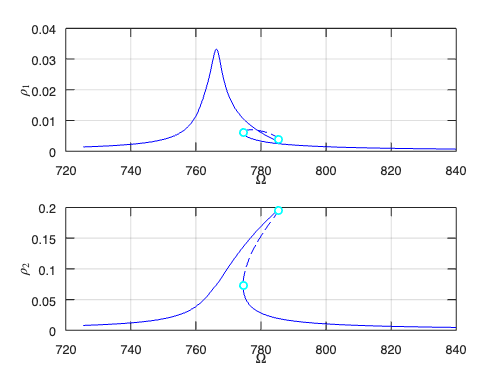

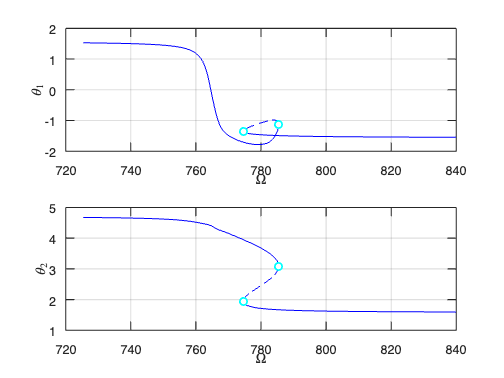

epsilon = [.2 .4];
mFreqs = [1 1];
resonantModes = [1 2 3 4];
omegaSpan =  [0.95 1.1]*imag(lambda(2));
% SSMLearn
[FRCSSMLearn] = continuationFRCep(IMInfoF, RDInfoF, epsilon, omegaSpan,@(x) x(outdof,:), mFreqs,resonantModes, 'SSMLearnvonKarmanPlateIR');

Due to high-dimensionality, we compute only the first 5 eigenvalues with the smallest magnitude. These would also be used to compute the spectral quotients
Assuming a proportional damping hypthesis with symmetric matrices
modal damping ratio for 1 mode is 2.243693e-03
modal damping ratio for 2 mode is 2.181986e-03
modal damping ratio for 3 mode is 2.186754e-03
modal damping ratio for 4 mode is 2.847788e-03
modal damping ratio for 5 mode is 3.388843e-03
the left eigenvectors may be incorrect in case of asymmetry of matrices

 The first 10 nonzero eigenvalues are given as 
     -0.68812 +     306.69i
     -0.68812 -     306.69i
      -1.6662 +     763.59i
      -1.6662 -     763.59i
      -1.6789 +     767.75i
      -1.6789 -     767.75i
      -3.4708 +     1218.8i
      -3.4708 -     1218.8i
      -5.1888 +     1531.1i
      -5.1888 -     1531.1i

(near) outer resonance detected for the following combination of master eigenvalues
     0     0     1     1
     0     1     1     0
     1 

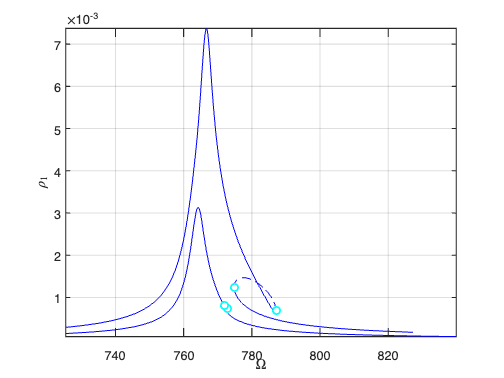

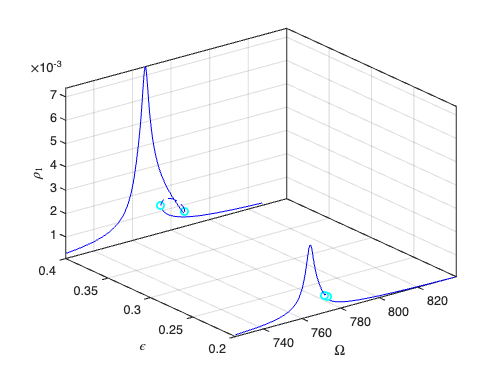

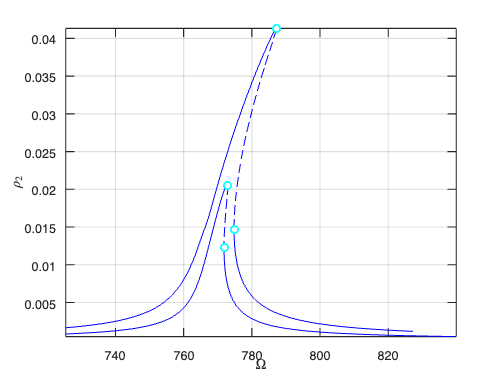

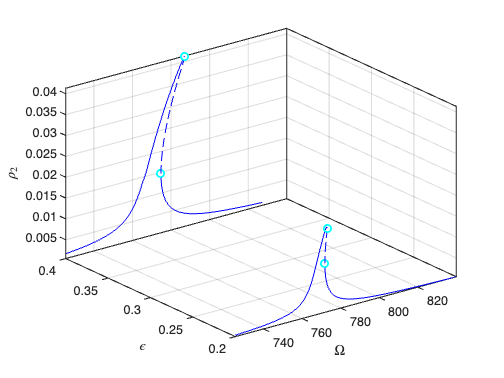

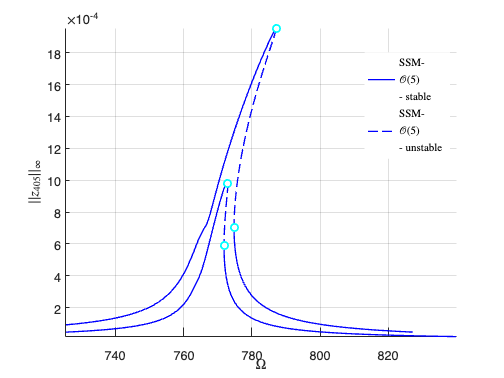

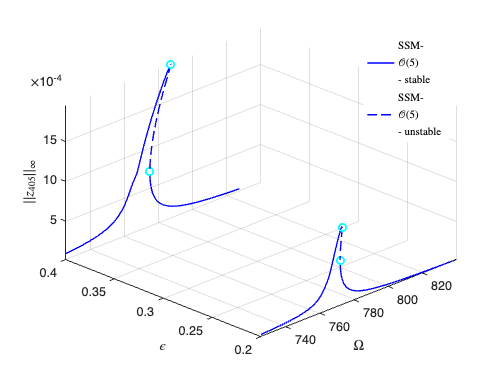

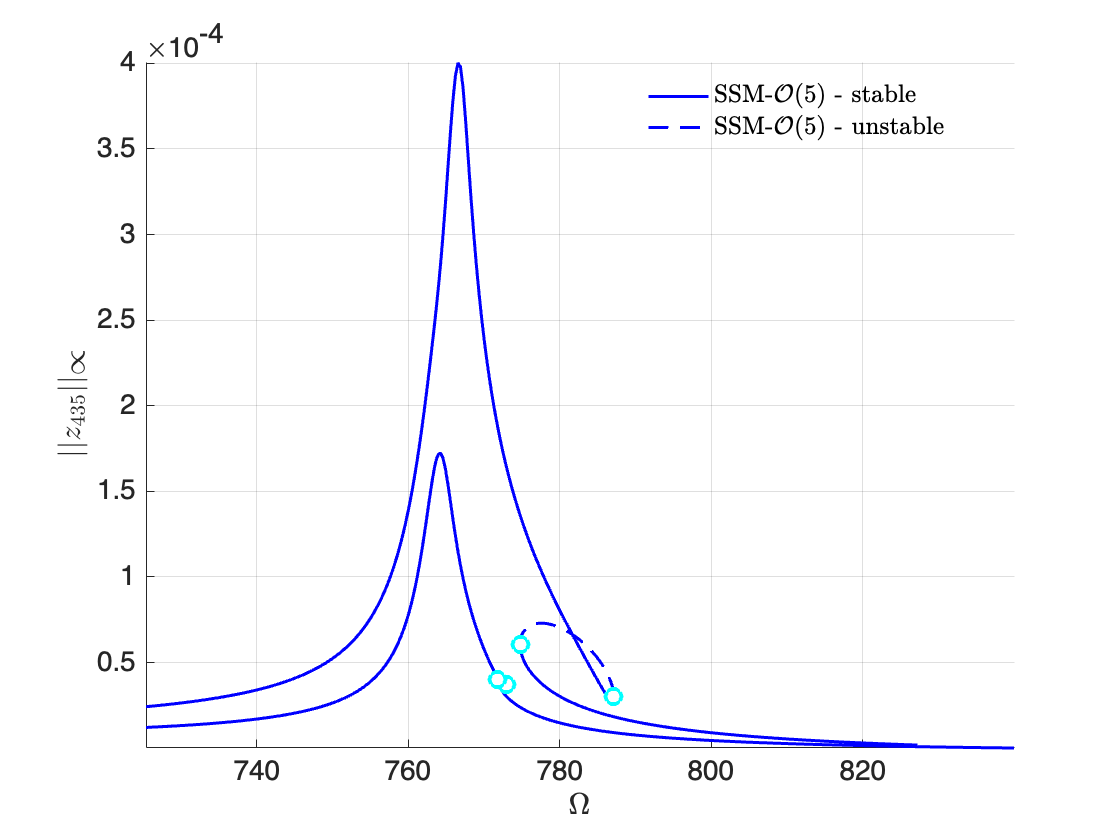

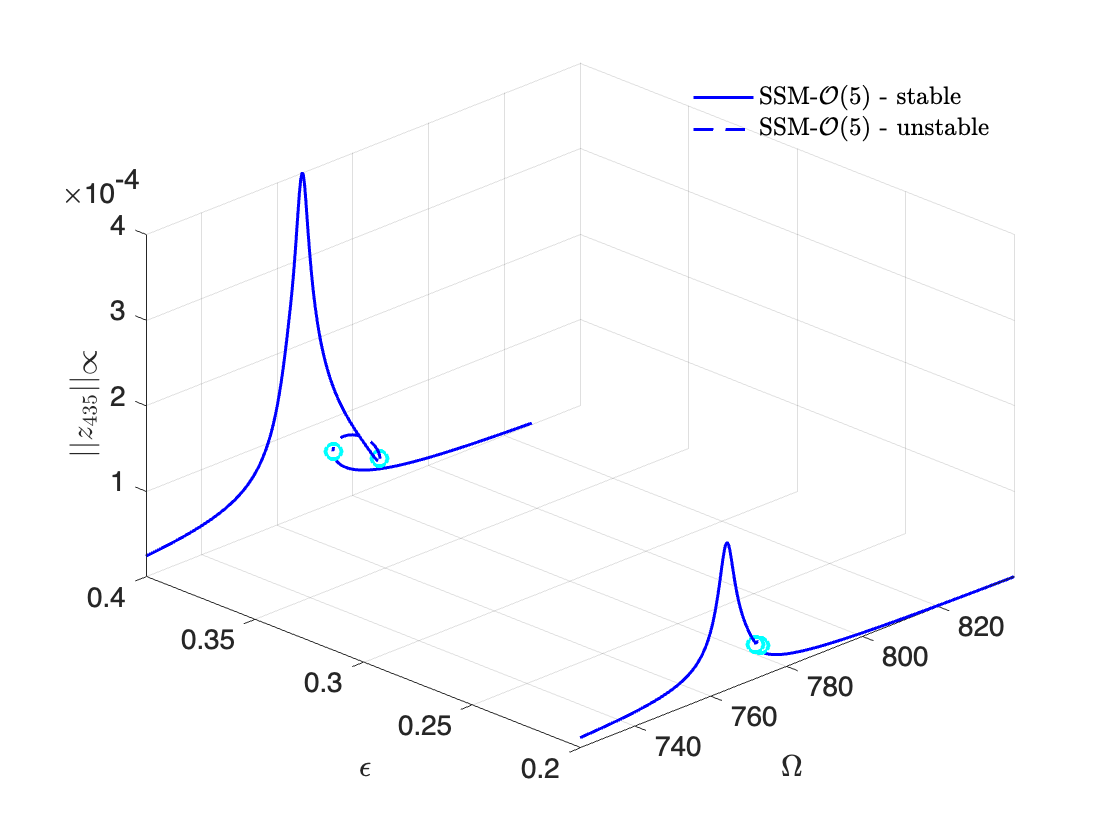

% SSMTool
[FRCSSMTool] = SSMToolFRCFE(M,C,K,fnl,M*forcingVectors(n+1:end),outdof,epsilon,[3:6],5,omegaSpan,mFreqs, 'SSMToolvonKarmanPlateIR');

## **Plot results**

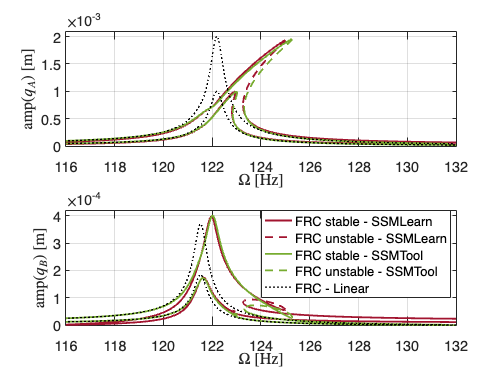

fig = customFigure('subPlot',[2 1]);
subplot(211)
plotFRC(FRCSSMLearn, colors(colSSML,:), '- SSMLearn','freqscale',2*pi)
plotFRC(FRCSSMTool, colors(colSSMT,:), '- SSMTool','freqscale',2*pi)
xlabel('$\Omega$ [Hz]','interpreter','latex')
ylabel('amp($q_{A}$) [m]','interpreter','latex')
legend('off')
xlim([ceil(omegaSpan(1)/2/pi) floor(omegaSpan(2)/2/pi)-1])
ylim([0 0.0021])
subplot(212)
plotFRC(FRCSSMLearn, colors(colSSML,:), '- SSMLearn','outamp',2,'freqscale',2*pi)
plotFRC(FRCSSMTool, colors(colSSMT,:), '- SSMTool','outamp',2,'freqscale',2*pi)
xlabel('$\Omega$ [Hz]','interpreter','latex')
ylabel('amp($q_{B}$) [m]','interpreter','latex')
xlim([ceil(omegaSpan(1)/2/pi) floor(omegaSpan(2)/2/pi)-1])
ylim([0 0.00042])

% Linear Response
LinResp = @(w) (-M*w^2+1i*w*C+K)\(M*forcingVectors(n+1:end));
omegaVec = linspace(omegaSpan(1),omegaSpan(2),1001);
ampVec = zeros(2,length(omegaVec));
for iW = 1:length(omegaVec)
    X0 = abs(LinResp(omegaVec(iW)));
    ampVec(:,iW) = X0(outdof);
end
for iEps = 1:length(epsilon)
    if iEps == 1; visib = 'on'; else; visib = 'off'; end 
    subplot(211)
    plot(omegaVec/2/pi,ampVec(1,:)*epsilon(iEps),'k:','DisplayName', 'FRC - Linear', 'Linewidth', 1.5,'HandleVisibility',visib)
    subplot(212)
    plot(omegaVec/2/pi,ampVec(2,:)*epsilon(iEps),'k:','DisplayName', 'FRC - Linear', 'Linewidth', 1.5,'HandleVisibility',visib)
end